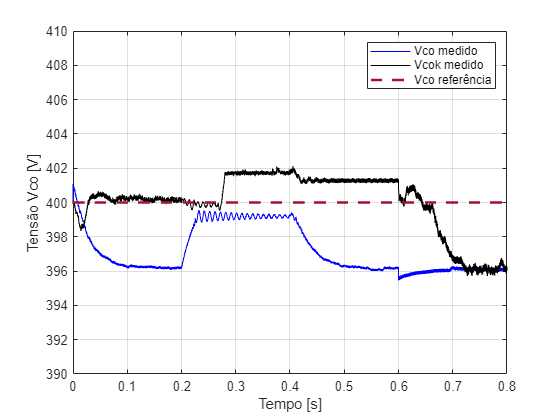

load("resultadoKalman.mat")


Vcok = out.Vok.signals(1).values;
Vcok_ref = out.Vok.signals(2).values;


load("ResultadoOriginal.mat")


Vco = out.Vco.signals(1).values;
t = linspace(0,0.8,length(Vco));

plot(t,Vco,"Color","b","DisplayName","Vco medido")
hold on
plot(t,Vcok,"Color","#000000","DisplayName","Vcok medido")
plot(t,Vco_ref,'--','LineWidth',2,"Color","#A2142F","DisplayName","Vco referência")
hold off
xlabel("Tempo [s]")
ylabel("Tensão Vco [V]")
axis([0 0.8 390 410])
legend
grid